### **1 Initialization**

%Initialization of fieldtrip
restoredefaultpath
fieldtrip_path = inputdlg("enter fieldtrip path:"); %/Users/sihanliang/Monkeylab/fieldtrip-20230613
addpath(fieldtrip_path{1})
ft_defaults

-------------------------------------------------------------------------------------------
FieldTrip is developed by members and collaborators of the Donders Institute for Brain,
Cognition and Behaviour at Radboud University, Nijmegen, the Netherlands.

                          --------------------------
                        /                            \
                     ------------------------------------
                    /                                    \
          -------------------------------------------------
         /                            /\/\/\/\/\ 
         ---------------------------------------------------
                  |        F  i  e  l  d  T  r  i  p       |
                  ------------------------------------------
                   \                                      /
                     ------------------------------------
                          \            /
                            ----------

Please cite the FieldTrip re


%Initialization of customized functions
function_path = inputdlg("enter function path:");
addpath(function_path{1})%/Users/sihanliang/monkeylab/LFP/code/functions

%set data directory as working directory
data_path = inputdlg("choose data path as working directory:")

data_path = 1×1 cell 数组
    {'/Users/sihanliang/monkeylab/LFP/data/EDF/data_aggregated'}


data_path = data_path{1};
cd(data_path)

%set bhv data path
bhv_path = inputdlg("enter the behaviors path:")

bhv_path = 1×1 cell 数组
    {'/Users/sihanliang/monkeylab/LFP/data/behaviors'}


bhv_path = bhv_path{1};
%'/Users/sihanliang/Monkeylab/LFP/data/behaviors';
 

### **2 Data Import and basic preprocessing**

[dataAll,orig_dataAll] = import_preprocess(data_path);


### ** 3 Artifact removal (Manual + Automatic ECG)**

checker has already been initialized.


dataset_checker = 1×99 cell 数组
    {[1]}    {[2]}    {[3]}    {[4]}    {[5]}    {[6]}    {[7]}    {[8]}    {[9]}    {[10]}    {[11]}    {[12]}    {[13]}    {[14]}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

Continuing


dataset_index = 14

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an est

cfg = 包含以下字段的 struct :
    viewmode: 'vertical'


the input is raw data with 1 channels and 1 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:
------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  :

cfg = 包含以下字段的 struct :
              viewmode: 'vertical'
            trackusage: '4D21ADF0'
           checkconfig: 'loose'
             checkpath: 'pedantic'
             checksize: 100000
              showlogo: 'yes'
          showcallinfo: 'yes'
                 debug: 'no'
     outputfilepresent: 'overwrite'
         trackcallinfo: 'yes'
         trackdatainfo: 'no'
         tracktimeinfo: 'yes'
          trackmeminfo: 'yes'
               toolbox: [1×1 struct]
          notification: [1×1 struct]
              callinfo: [1×1 struct]
               version: [1×1 struct]
               preproc: [1×1 struct]
                  ylim: [-1406 1406]
                  zlim: 'maxmin'
             artfctdef: [1×1 struct]
            selectmode: 'markartifact'
             blocksize: 1
                selfun: {'simpleFFT'  'multiplotER'  'topoplotER'  'topoplotVAR'  'movieplotER'  'audiovideo'}
                selcfg: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1

artifact_index = 1×4 cell 数组
    {3×2 double}    {0×0 double}    {0×0 double}    {0×0 double}


cfg = 包含以下字段的 struct :
              viewmode: 'vertical'
            trackusage: '4D21ADF0'
           checkconfig: 'loose'
             checkpath: 'pedantic'
             checksize: 100000
              showlogo: 'yes'
          showcallinfo: 'yes'
                 debug: 'no'
     outputfilepresent: 'overwrite'
         trackcallinfo: 'yes'
         trackdatainfo: 'no'
         tracktimeinfo: 'yes'
          trackmeminfo: 'yes'
               toolbox: [1×1 struct]
          notification: [1×1 struct]
              callinfo: [1×1 struct]
               version: [1×1 struct]
               preproc: [1×1 struct]
                  ylim: [-1406 1406]
                  zlim: 'maxmin'
             artfctdef: [1×1 struct]
            selectmode: 'markartifact'
             blocksize: 1
                selfun: {'simpleFFT'  'multiplotER'  'topoplotER'  'topoplotVAR'  'movieplotER'  'audiovideo'}
                selcfg: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1

detected   3 visual artifacts
rejected   0 trials completely
rejected   0 trials partially
filled parts of   0 trials with NaNs
filled parts of   1 trials with zeros
filled parts of   0 trials with a specified value
resulting   1 trials
the call to "ft_rejectartifact" took 0 seconds and required the additional allocation of an estimated 0 MB


data_list = 1×4 cell 数组
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


cfg = 包含以下字段的 struct :
    viewmode: 'vertical'


the input is raw data with 1 channels and 1 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:
------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  :

cfg = 包含以下字段的 struct :
              viewmode: 'vertical'
            trackusage: '4D21ADF0'
           checkconfig: 'loose'
             checkpath: 'pedantic'
             checksize: 100000
              showlogo: 'yes'
          showcallinfo: 'yes'
                 debug: 'no'
     outputfilepresent: 'overwrite'
         trackcallinfo: 'yes'
         trackdatainfo: 'no'
         tracktimeinfo: 'yes'
          trackmeminfo: 'yes'
               toolbox: [1×1 struct]
          notification: [1×1 struct]
              callinfo: [1×1 struct]
               version: [1×1 struct]
               preproc: [1×1 struct]
                  ylim: [-166.2000 166.2000]
                  zlim: 'maxmin'
             artfctdef: [1×1 struct]
            selectmode: 'markartifact'
             blocksize: 1
                selfun: {'simpleFFT'  'multiplotER'  'topoplotER'  'topoplotVAR'  'movieplotER'  'audiovideo'}
                selcfg: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 str

artifact_index = 1×4 cell 数组
    {3×2 double}    {[1 124085]}    {0×0 double}    {0×0 double}


cfg = 包含以下字段的 struct :
              viewmode: 'vertical'
            trackusage: '4D21ADF0'
           checkconfig: 'loose'
             checkpath: 'pedantic'
             checksize: 100000
              showlogo: 'yes'
          showcallinfo: 'yes'
                 debug: 'no'
     outputfilepresent: 'overwrite'
         trackcallinfo: 'yes'
         trackdatainfo: 'no'
         tracktimeinfo: 'yes'
          trackmeminfo: 'yes'
               toolbox: [1×1 struct]
          notification: [1×1 struct]
              callinfo: [1×1 struct]
               version: [1×1 struct]
               preproc: [1×1 struct]
                  ylim: [-166.2000 166.2000]
                  zlim: 'maxmin'
             artfctdef: [1×1 struct]
            selectmode: 'markartifact'
             blocksize: 1
                selfun: {'simpleFFT'  'multiplotER'  'topoplotER'  'topoplotVAR'  'movieplotER'  'audiovideo'}
                selcfg: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 str

detected   1 visual artifacts
rejected   0 trials completely
rejected   0 trials partially
filled parts of   0 trials with NaNs
filled parts of   1 trials with zeros
filled parts of   0 trials with a specified value
resulting   1 trials
the call to "ft_rejectartifact" took 0 seconds and required the additional allocation of an estimated 0 MB


data_list = 1×4 cell 数组
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


cfg = 包含以下字段的 struct :
    viewmode: 'vertical'


the input is raw data with 1 channels and 1 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:
------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  :

cfg = 包含以下字段的 struct :
              viewmode: 'vertical'
            trackusage: '4D21ADF0'
           checkconfig: 'loose'
             checkpath: 'pedantic'
             checksize: 100000
              showlogo: 'yes'
          showcallinfo: 'yes'
                 debug: 'no'
     outputfilepresent: 'overwrite'
         trackcallinfo: 'yes'
         trackdatainfo: 'no'
         tracktimeinfo: 'yes'
          trackmeminfo: 'yes'
               toolbox: [1×1 struct]
          notification: [1×1 struct]
              callinfo: [1×1 struct]
               version: [1×1 struct]
               preproc: [1×1 struct]
                  ylim: [-1670 1670]
                  zlim: 'maxmin'
             artfctdef: [1×1 struct]
            selectmode: 'markartifact'
             blocksize: 1
                selfun: {'simpleFFT'  'multiplotER'  'topoplotER'  'topoplotVAR'  'movieplotER'  'audiovideo'}
                selcfg: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1

artifact_index = 1×4 cell 数组
    {3×2 double}    {[1 124085]}    {3×2 double}    {0×0 double}


cfg = 包含以下字段的 struct :
              viewmode: 'vertical'
            trackusage: '4D21ADF0'
           checkconfig: 'loose'
             checkpath: 'pedantic'
             checksize: 100000
              showlogo: 'yes'
          showcallinfo: 'yes'
                 debug: 'no'
     outputfilepresent: 'overwrite'
         trackcallinfo: 'yes'
         trackdatainfo: 'no'
         tracktimeinfo: 'yes'
          trackmeminfo: 'yes'
               toolbox: [1×1 struct]
          notification: [1×1 struct]
              callinfo: [1×1 struct]
               version: [1×1 struct]
               preproc: [1×1 struct]
                  ylim: [-1670 1670]
                  zlim: 'maxmin'
             artfctdef: [1×1 struct]
            selectmode: 'markartifact'
             blocksize: 1
                selfun: {'simpleFFT'  'multiplotER'  'topoplotER'  'topoplotVAR'  'movieplotER'  'audiovideo'}
                selcfg: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1

detected   3 visual artifacts
rejected   0 trials completely
rejected   0 trials partially
filled parts of   0 trials with NaNs
filled parts of   1 trials with zeros
filled parts of   0 trials with a specified value
resulting   1 trials
the call to "ft_rejectartifact" took 0 seconds and required the additional allocation of an estimated 0 MB


data_list = 1×4 cell 数组
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


cfg = 包含以下字段的 struct :
    viewmode: 'vertical'


the input is raw data with 1 channels and 1 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:
------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  :

cfg = 包含以下字段的 struct :
              viewmode: 'vertical'
            trackusage: '4D21ADF0'
           checkconfig: 'loose'
             checkpath: 'pedantic'
             checksize: 100000
              showlogo: 'yes'
          showcallinfo: 'yes'
                 debug: 'no'
     outputfilepresent: 'overwrite'
         trackcallinfo: 'yes'
         trackdatainfo: 'no'
         tracktimeinfo: 'yes'
          trackmeminfo: 'yes'
               toolbox: [1×1 struct]
          notification: [1×1 struct]
              callinfo: [1×1 struct]
               version: [1×1 struct]
               preproc: [1×1 struct]
                  ylim: [-304 304]
                  zlim: 'maxmin'
             artfctdef: [1×1 struct]
            selectmode: 'markartifact'
             blocksize: 1
                selfun: {'simpleFFT'  'multiplotER'  'topoplotER'  'topoplotVAR'  'movieplotER'  'audiovideo'}
                selcfg: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1

artifact_index = 1×4 cell 数组
    {3×2 double}    {[1 124085]}    {3×2 double}    {2×2 double}


cfg = 包含以下字段的 struct :
              viewmode: 'vertical'
            trackusage: '4D21ADF0'
           checkconfig: 'loose'
             checkpath: 'pedantic'
             checksize: 100000
              showlogo: 'yes'
          showcallinfo: 'yes'
                 debug: 'no'
     outputfilepresent: 'overwrite'
         trackcallinfo: 'yes'
         trackdatainfo: 'no'
         tracktimeinfo: 'yes'
          trackmeminfo: 'yes'
               toolbox: [1×1 struct]
          notification: [1×1 struct]
              callinfo: [1×1 struct]
               version: [1×1 struct]
               preproc: [1×1 struct]
                  ylim: [-304 304]
                  zlim: 'maxmin'
             artfctdef: [1×1 struct]
            selectmode: 'markartifact'
             blocksize: 1
                selfun: {'simpleFFT'  'multiplotER'  'topoplotER'  'topoplotVAR'  'movieplotER'  'audiovideo'}
                selcfg: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1

detected   2 visual artifacts
rejected   0 trials completely
rejected   0 trials partially
filled parts of   0 trials with NaNs
filled parts of   1 trials with zeros
filled parts of   0 trials with a specified value
resulting   1 trials
the call to "ft_rejectartifact" took 0 seconds and required the additional allocation of an estimated 0 MB


data_list = 1×4 cell 数组
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


concatenating over the "chan" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB


dataAll = 1×99 cell 数组
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct} 

nonempty_dataset_checker = 1×14 cell 数组
    {[1]}    {[2]}    {[3]}    {[4]}    {[5]}    {[6]}    {[7]}    {[8]}    {[9]}    {[10]}    {[11]}    {[12]}    {[13]}    {[14]}


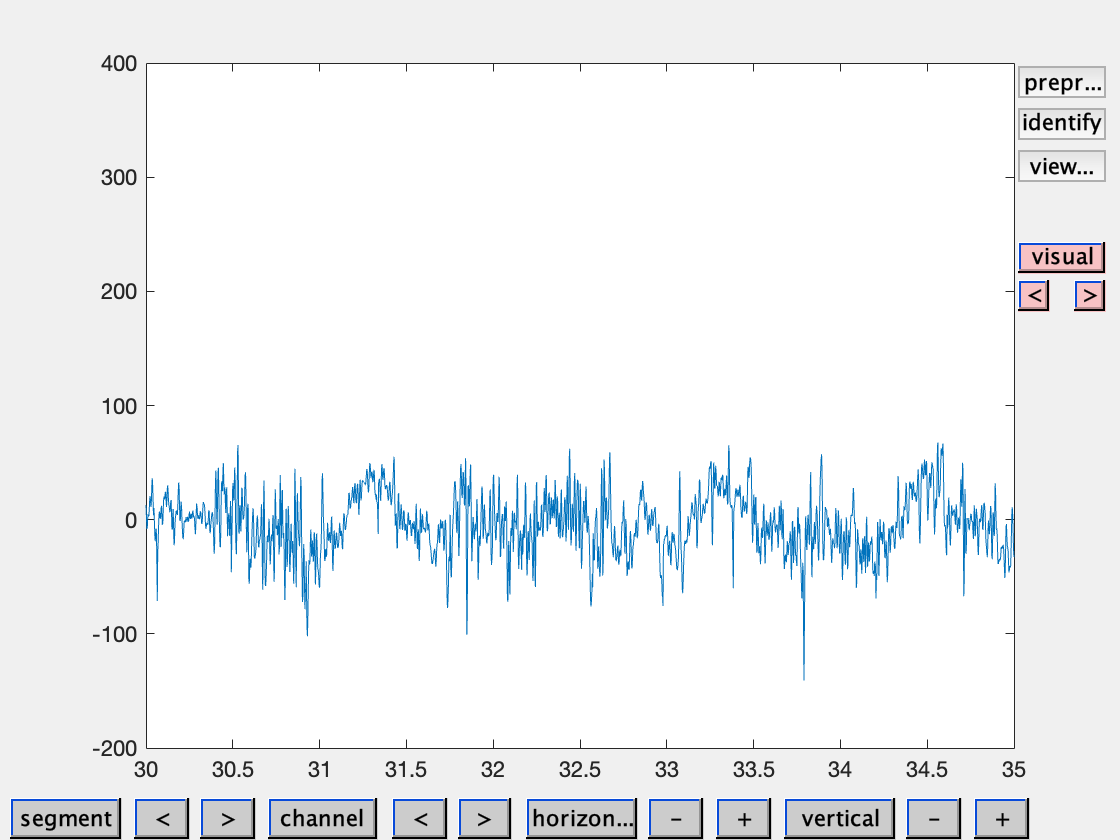

dataset_checker = 1×99 cell 数组
    {[1]}    {[2]}    {[3]}    {[4]}    {[5]}    {[6]}    {[7]}    {[8]}    {[9]}    {[10]}    {[11]}    {[12]}    {[13]}    {[14]}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

ans = '/Users/sihanliang/monkeylab/LFP/data/EDF/data_aggregated/1030L00023_2023_10_31_10_06_20.edf'

[dataAll,dataset_checker] = remove_artifacts(dataAll,orig_dataAll);

Next: maybe first separate each dataset by channel and combine the datasets for each channel for each day? so that you would get amount_of_channels datasets of very long length CONTINUOUS DATA as the end product. This way, although you won't be able to analyze the connectivity between channels(since the record timing and synchrony between channels have been disrupted), but seems really easy for the biomarkers during symptom analysis part.

Modification: this should still be after data segementation step. AND THE COMBINED DATA SHOULD NOT BE CONTINOUS BUT SEGMENTED DATA EPOCHES OF SYMPTOM ONSETS. Otherwise data segmentation would be a pain.

### 4 Data segmentation by event markers

[dataAll_by_dates,dataSegments] = segment_data(dataAll,dataset_checker,bhv_path);

Continuing


data_current_date = 1×4 cell 数组
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


eventData_all_sessions = 1×4 cell 数组
    {5×4 table}    {5×4 table}    {0×0 double}    {0×0 double}


eventData_all_sessions = 1×4 cell 数组
    {5×4 table}    {5×4 table}    {0×0 double}    {0×0 double}


ans = datetime
   12:53:51


ans = datetime
   13:00:00


dataAll_by_dates = 包含以下字段的 struct :
    data_20231030: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    data_20231027: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}


the input is raw data with 4 channels and 1 trials


 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 90
 In ft_checkdata at line 279
 In ft_redefinetrial at line 110



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 90
 In ft_checkdata at line 279
 In ft_redefinetrial at line 110



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 90
 In ft_checkdata at line 279
 In ft_redefinetrial at line 110



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_redefinetrial at line 110



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_redefinetrial at line 110



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_redefinetrial at line 110



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_redefinetrial at line 253



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_redefinetrial at line 253



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_redefinetrial at line 253



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_fetch_header at line 32
 In 

 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_fetch_header at line 32
 In 

 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_fetch_header at line 32
 In 

 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 90
 In ft_checkdata at line 279
 In ft_redefinetrial at line 110



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 90
 In ft_checkdata at line 279
 In ft_redefinetrial at line 110



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 90
 In ft_checkdata at line 279
 In ft_redefinetrial at line 110



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_redefinetrial at line 110



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_redefinetrial at line 110



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_redefinetrial at line 110



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_redefinetrial at line 253



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_redefinetrial at line 253



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_redefinetrial at line 253



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_fetch_header at line 32
 In 

 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_fetch_header at line 32
 In 

 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_fetch_header at line 32
 In 

 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 90
 In ft_checkdata at line 279
 In ft_redefinetrial at line 110



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 90
 In ft_checkdata at line 279
 In ft_redefinetrial at line 110



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 90
 In ft_checkdata at line 279
 In ft_redefinetrial at line 110



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_redefinetrial at line 110



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_redefinetrial at line 110



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_redefinetrial at line 110



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_redefinetrial at line 253



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_redefinetrial at line 253



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_redefinetrial at line 253



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_fetch_header at line 32
 In 

 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_fetch_header at line 32
 In 

 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_fetch_header at line 32
 In 

 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 90
 In ft_checkdata at line 279
 In ft_redefinetrial at line 110



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 90
 In ft_checkdata at line 279
 In ft_redefinetrial at line 110



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 90
 In ft_checkdata at line 279
 In ft_redefinetrial at line 110



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_redefinetrial at line 110



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_redefinetrial at line 110



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_redefinetrial at line 110



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_redefinetrial at line 253



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_redefinetrial at line 253



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_redefinetrial at line 253



 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_fetch_header at line 32
 In 

 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_fetch_header at line 32
 In 

 In getdimord>warning_dimord_could_not_be_determined at line 785
 In getdimord at line 735
 In makessense at line 41
 In ft_datatype_raw at line 95
 In ft_checkdata at line 279
 In ft_fetch_header at line 32
 In 

dataAll_by_dates = 包含以下字段的 struct :
    data_20231030: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    data_20231027: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}


dataSegments = 包含以下字段的 struct :
    data_20231030: [1×8 struct]
    data_20231027: [1×4 struct]


afterwards you can get each channel's data of each day, and concatenate the data from different days by channel. 

Get aggregated segments for each channel

### **5 Aggregation of Data Segments by channel**

symptom_segments_c0 = segments_by_channel(dataSegments,'C_0','symptom_onset');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 8 MB
preprocessing
preprocessing trial 2 from 2

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 16 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 2 from 2

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 5 from 5

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 4 from 4

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an es

 In ft_appenddata at line 94



 In ft_appenddata at line 95

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 4 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 10 MB


save("symptom_segments_c0.mat","symptom_segments_c0")
symptom_segments_c1 = segments_by_channel(dataSegments,'C_1','symptom_onset');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 2 from 2

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 2 from 2

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 5 from 5

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 4 from 4

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an est

 In ft_appenddata at line 94



 In ft_appenddata at line 95

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB


symptom_segments_c2 = segments_by_channel(dataSegments,'C_2','symptom_onset');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 9 from 9

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 10 from 10

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 5 from 5

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB


 In ft_appenddata at line 94



 In ft_appenddata at line 95

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 1 MB


symptom_segments_c4 = segments_by_channel(dataSegments,'C_4','symptom_onset');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 9 from 9

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 10 from 10

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 5 from 5

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB


 In ft_appenddata at line 94



 In ft_appenddata at line 95

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB


symptom_segments_c5 = segments_by_channel(dataSegments,'C_5','symptom_onset');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 5 from 5

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 2 MB


symptom_segments_c6 = segments_by_channel(dataSegments,'C_6','symptom_onset');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 5 from 5

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB


symptom_segments_c8 = segments_by_channel(dataSegments,'C_8','symptom_onset');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 2 from 2

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 5 from 5

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 5 from 5

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB


 In ft_appenddata at line 94



 In ft_appenddata at line 95

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB


symptom_segments_c9 = segments_by_channel(dataSegments,'C_9','symptom_onset');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 2 from 2

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 5 from 5

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 5 from 5

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB


 In ft_appenddata at line 94



 In ft_appenddata at line 95

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB


symptom_segments_c10 = segments_by_channel(dataSegments,'C_10','symptom_onset');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 9 from 9

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 10 from 10

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 5 from 5

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB


 In ft_appenddata at line 94



 In ft_appenddata at line 95

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB


symptom_segments_c11 = segments_by_channel(dataSegments,'C_11','symptom_onset');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 9 from 9

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 10 from 10

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 5 from 5

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB


 In ft_appenddata at line 94



 In ft_appenddata at line 95

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB


symptom_segments_c12 = segments_by_channel(dataSegments,'C_12','symptom_onset');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 5 from 5

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB


symptom_segments_c13 = segments_by_channel(dataSegments,'C_13','symptom_onset');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 5 from 5

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB


symptom_segments_c14 = segments_by_channel(dataSegments,'C_14','symptom_onset');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 2 from 2

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 4 from 4

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB


 In ft_appenddata at line 94



 In ft_appenddata at line 95

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 1 MB


symptom_segments_c15 = segments_by_channel(dataSegments,'C_15','symptom_onset');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 2 from 2

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 4 from 4

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB


 In ft_appenddata at line 94



 In ft_appenddata at line 95

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB





baseline_segments_c0 = segments_by_channel(dataSegments,'C_0','non_event');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 3 from 3

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 3 from 3

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 6 from 6

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 4 MB
preprocessing
preprocessing trial 5 from 5

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 3 MB
preprocessing
preprocessing trial 5 from 5

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 3 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 2 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 2 MB


 In ft_appenddata at line 94



 In ft_appenddata at line 95

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 1 MB


save("baseline_segments_c0.mat","baseline_segments_c0")

baseline_segments_c1 = segments_by_channel(dataSegments,'C_1','non_event');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 3 from 3

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 3 from 3

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 6 from 6

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 5 from 5

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 5 from 5

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 2 MB


 In ft_appenddata at line 94



 In ft_appenddata at line 95

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB


baseline_segments_c2 = segments_by_channel(dataSegments,'C_2','non_event');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 10 from 10

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 11 from 11

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 6 from 6

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


 In ft_appenddata at line 94



 In ft_appenddata at line 95

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB


baseline_segments_c4 = segments_by_channel(dataSegments,'C_4','non_event');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 10 from 10

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 11 from 11

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 6 from 6

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


 In ft_appenddata at line 94



 In ft_appenddata at line 95

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB


baseline_segments_c5 = segments_by_channel(dataSegments,'C_5','non_event');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 6 from 6

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


 In ft_appenddata at line 94



 In ft_appenddata at line 95

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB


baseline_segments_c6 = segments_by_channel(dataSegments,'C_6','non_event');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 6 from 6

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 5 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 2 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 4 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


 In ft_appenddata at line 94



 In ft_appenddata at line 95

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB


baseline_segments_c8 = segments_by_channel(dataSegments,'C_8','non_event');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 3 from 3

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 6 from 6

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 5 from 5

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


 In ft_appenddata at line 94



 In ft_appenddata at line 95

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB


baseline_segments_c9 = segments_by_channel(dataSegments,'C_9','non_event');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
preprocessing
preprocessing trial 3 from 3

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 6 from 6

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 5 from 5

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


 In ft_appenddata at line 94



 In ft_appenddata at line 95

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB


baseline_segments_c10 = segments_by_channel(dataSegments,'C_10','non_event');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
preprocessing
preprocessing trial 10 from 10

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 11 from 11

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 2 MB
preprocessing
preprocessing trial 6 from 6

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 3 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


 In ft_appenddata at line 94



 In ft_appenddata at line 95

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB


baseline_segments_c11 = segments_by_channel(dataSegments,'C_11','non_event');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 10 from 10

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 11 from 11

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 6 from 6

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


 In ft_appenddata at line 94



 In ft_appenddata at line 95

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB


baseline_segments_c12 = segments_by_channel(dataSegments,'C_12','non_event');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 6 from 6

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 2 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


 In ft_appenddata at line 94



 In ft_appenddata at line 95

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB


baseline_segments_c13 = segments_by_channel(dataSegments,'C_13','non_event');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 6 from 6

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 2 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


 In ft_appenddata at line 94



 In ft_appenddata at line 95

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB


baseline_segments_c14 = segments_by_channel(dataSegments,'C_14','non_event');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 3 from 3

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 5 from 5

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 2 MB


 In ft_appenddata at line 94



 In ft_appenddata at line 95

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB


baseline_segments_c15 = segments_by_channel(dataSegments,'C_15','non_event');

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 3 from 3

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 5 from 5

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


data = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124085]
         trial: {[4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB


 In ft_appenddata at line 94



 In ft_appenddata at line 95

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB